clear all;close all;

Error using close
Reference to non-existent field 'deviceObj'.

Error in close


% THEORIQUE
dphi = linspace(0,2*pi,360);
I1 = 1;I2 = 1;

Vs = I1+I2+2*sqrt(I1*I2)*cos(dphi);

plot(dphi,Vs)
xlabel('Angle (rad)')
ylabel('Intensité Lumineuse (W/m^2)')
title('Mesure préliminaire')
legend('théorique','location','best')
grid minor

Si on veut pas déformer un signal -> Fonction linéaire

## PARTIE 2

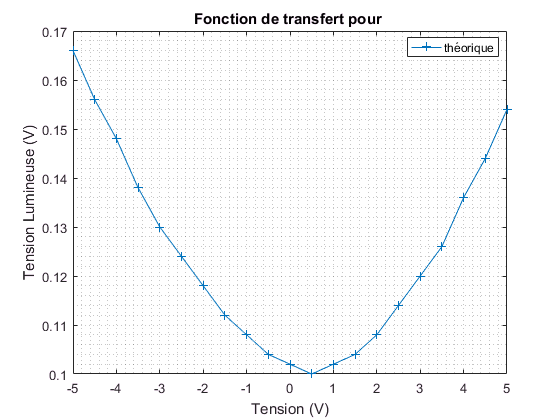

% PRATIQUE
V = -5:0.5:5;
Vs = [166 156 148 138 130 124 118 112 108 104 102 100 102 104 108 114 120 126 136 144 154]*1e-3;
figure
plot(V,Vs,'+-')
xlabel('Tension (V)')
ylabel('Tension Lumineuse (V)')
title('Fonction de transfert pour ')
legend('théorique','location','best')
grid minor

On peut pas calculer $V_{\pi }$ car on n'a pas pas deux valeurs max.

## PARTIE 3

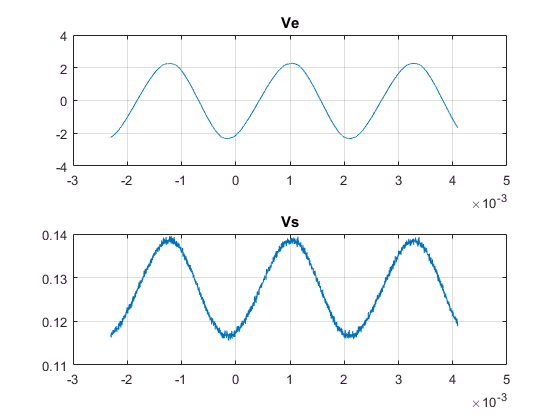

load ch11.dat
load ch21.dat
figure
subplot(211)
plot(ch21(:,1),ch21(:,2))
title('Ve')
grid on
subplot(212)
plot(ch11(:,1),ch11(:,2))
title('Vs')
grid on

Dans le cas ou on est dans la zone linéaire (3.5V) et avec Ve amplitude faible, on a une transmission parfaite.

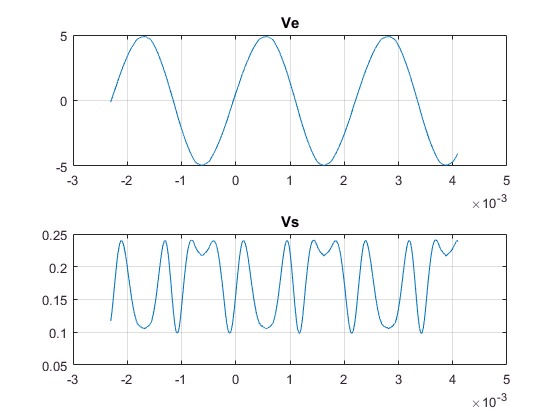

load ch12.dat
load ch22.dat
figure
subplot(211)
plot(ch22(:,1),ch22(:,2))
title('Ve')
grid on
subplot(212)
plot(ch12(:,1),ch12(:,2))
title('Vs')
grid on

Dans le cas où Ve a une amplitude élevé, la transmission est mauvaise car le signal, bien que 

2) En zone non linéaire (sommet ou creux), augmenter l'amplitude accentue la déformation du signal.

Pour transmettre le signal le plus fidèlement, il faut une amplitude faible.

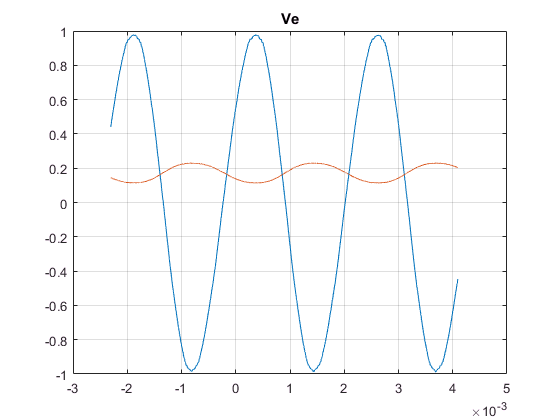

load ch13.dat
load ch23.dat
figure
plot(ch23(:,1),ch23(:,2),ch13(:,1),ch13(:,2))
title('Ve')
grid on

La phase n'a aucun import dans la perception du signal.

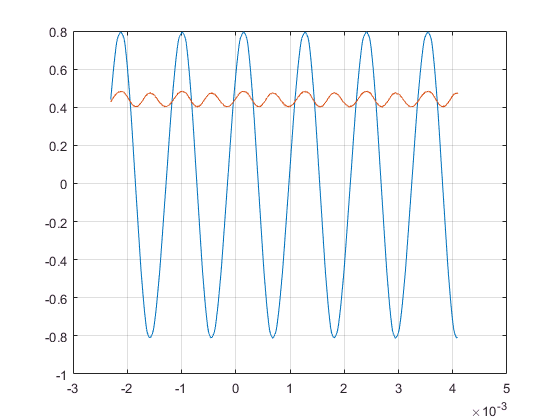

load ch14.dat
load ch24.dat
figure
plot(ch24(:,1),ch24(:,2),ch14(:,1),ch14(:,2)*4)

grid on

Lorsque l'on double la fréquence Ve, on quadruple la fréquence de Vs. C'est à dire que augmenter d'une octave Ve fera que l'on augmenter de deux octaves Vs.

Le signal de la radio est archaique, à l'inverse du signal précédent (monochromatique). Modifier la valeur de la tension DC modifiera la qualité ainsi que son niveau sonore.

Si l'on augmente trop le son de l'ordinateur, on entend du bruit. Augmenter le son équivaut à faire varier son amplitude, et tout comme le son monochromatique, une amplitude trop importante aura pour conséquence que certaines partie de Vs seront sur les zones non-linéaires.

# Q3.9

F=10Ghz et Power=13dBm

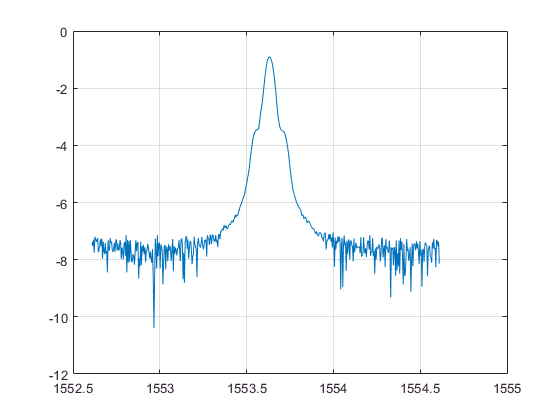

load WaveData20230323_000.csv
plot(WaveData20230323_000(:,1),log10(WaveData20230323_000(:,2)))
xlim auto
grid on

10) Pour une transmission d'un signal 5GHz, nous ne voyons plus le signal car il n'est plus dans la résolution de l'analyseur de spectre (RBW etc).